% Load the dataset
processed_data = readtable('processed_Traffic_Trajectory_Dataset_final.csv');

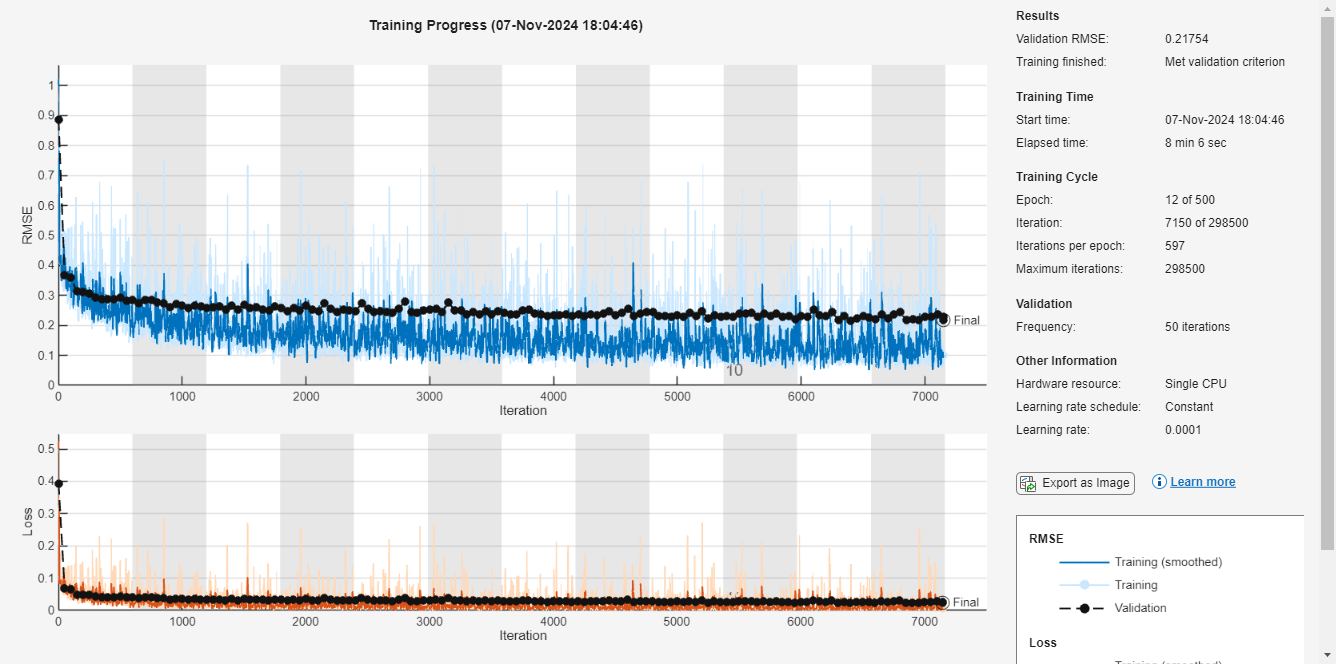


% Remove missing values
processed_data = rmmissing(processed_data);

% Extract features and targets
X = processed_data{:, {'Speed', 'Acceleration', 'Heading', 'HeadingChange', 'Latitude', 'Longitude'}};
y_latitude = processed_data.FutureLatitude;
y_longitude = processed_data.FutureLongitude;

% Normalize the features
[X, mu, sigma] = normalize(X);  % Normalize input features (zero mean, unit variance)

% Standardize the target variables
y_latitude_mean = mean(y_latitude);
y_latitude_std = std(y_latitude);
y_latitude = (y_latitude - y_latitude_mean) / y_latitude_std;

y_longitude_mean = mean(y_longitude);
y_longitude_std = std(y_longitude);
y_longitude = (y_longitude - y_longitude_mean) / y_longitude_std;

% Split the data into training and testing sets (80% training, 20% testing)
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv), :);
X_test = X(test(cv), :);
y_latitude_train = y_latitude(training(cv), :);
y_latitude_test = y_latitude(test(cv), :);
y_longitude_train = y_longitude(training(cv), :);
y_longitude_test = y_longitude(test(cv), :);

% Define the number of time steps for the LSTM model (increased to capture more temporal context)
numTimeSteps = 10;

% Prepare sequential data for training
numTrainSamples = size(X_train, 1) - numTimeSteps;
X_train_seq = cell(numTrainSamples, 1);
y_latitude_train_seq = zeros(numTrainSamples, 1);
y_longitude_train_seq = zeros(numTrainSamples, 1);

for i = 1:numTrainSamples
    X_train_seq{i} = X_train(i:i+numTimeSteps-1, :)';
    y_latitude_train_seq(i) = y_latitude_train(i + numTimeSteps);
    y_longitude_train_seq(i) = y_longitude_train(i + numTimeSteps);
end

% Prepare sequential data for testing
numTestSamples = size(X_test, 1) - numTimeSteps;
X_test_seq = cell(numTestSamples, 1);
y_latitude_test_seq = zeros(numTestSamples, 1);
y_longitude_test_seq = zeros(numTestSamples, 1);

for i = 1:numTestSamples
    X_test_seq{i} = X_test(i:i+numTimeSteps-1, :)';
    y_latitude_test_seq(i) = y_latitude_test(i + numTimeSteps);
    y_longitude_test_seq(i) = y_longitude_test(i + numTimeSteps);
end

% Define the LSTM network parameters
inputSize = 6;
numHiddenUnits_lat = 200;
numHiddenUnits_long = 200;
numResponses = 1;

% Define the LSTM network for latitude prediction with additional layers and batch normalization
layers_lat = [
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits_lat, 'OutputMode', 'sequence')
    batchNormalizationLayer
    lstmLayer(numHiddenUnits_lat, 'OutputMode', 'last')
    dropoutLayer(0.3)  % Dropout rate adjusted for better regularization
    fullyConnectedLayer(numResponses)
    regressionLayer];

% Define training options for the latitude model
options_lat = trainingOptions('adam', ...
    'MaxEpochs', 500, ...  % Increased epochs for better convergence
    'MiniBatchSize', 64, ...  % Reduced batch size for better convergence
    'InitialLearnRate', 0.0001, ...
    'L2Regularization', 0.001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {X_test_seq, y_latitude_test_seq}, ...
    'ValidationFrequency', 50, ...
    'ValidationPatience', 15, ...
    'Plots', 'training-progress', ...
    'Verbose', 0);

% Train the LSTM model for latitude prediction
LSTMModel_lat = trainNetwork(X_train_seq, y_latitude_train_seq, layers_lat, options_lat);

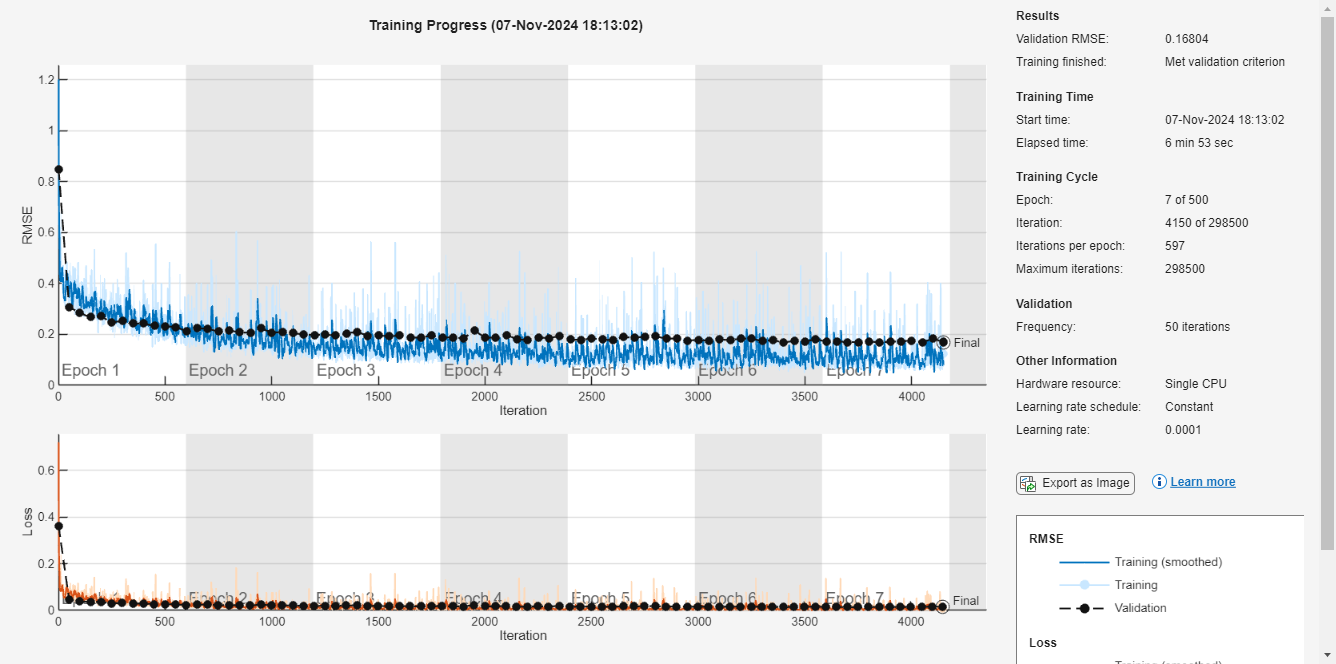


% Define the LSTM network for longitude prediction with bi-directional LSTM
layers_long = [
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits_long, 'OutputMode', 'sequence')  % Using Bi-LSTM for better sequence learning
    batchNormalizationLayer
    lstmLayer(numHiddenUnits_long, 'OutputMode', 'last')
    dropoutLayer(0.3)
    fullyConnectedLayer(numResponses)
    regressionLayer];

% Define training options for the longitude model
options_long = trainingOptions('adam', ...
    'MaxEpochs', 500, ...
    'MiniBatchSize', 64, ...
    'InitialLearnRate', 0.0001, ...
    'L2Regularization', 0.001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {X_test_seq, y_longitude_test_seq}, ...
    'ValidationFrequency', 50, ...
    'ValidationPatience', 15, ...
    'Plots', 'training-progress', ...
    'Verbose', 0);

% Train the LSTM model for longitude prediction
LSTMModel_long = trainNetwork(X_train_seq, y_longitude_train_seq, layers_long, options_long);


% Use the trained models to predict future values on the test set
y_latitude_pred = predict(LSTMModel_lat, X_test_seq);
y_longitude_pred = predict(LSTMModel_long, X_test_seq);

% Convert predictions back to original scale
y_latitude_pred = y_latitude_pred * y_latitude_std + y_latitude_mean;
y_longitude_pred = y_longitude_pred * y_longitude_std + y_longitude_mean;

y_latitude_test_seq = y_latitude_test_seq * y_latitude_std + y_latitude_mean;
y_longitude_test_seq = y_longitude_test_seq * y_longitude_std + y_longitude_mean;

% Calculate the Mean Squared Error (MSE) for both predictions
mse_latitude = mean((y_latitude_pred - y_latitude_test_seq).^2);
mse_longitude = mean((y_longitude_pred - y_longitude_test_seq).^2);

% Display the results for MSE
disp(['Mean Squared Error for Latitude Prediction: ', num2str(mse_latitude)]);

Mean Squared Error for Latitude Prediction: 0.0001877


disp(['Mean Squared Error for Longitude Prediction: ', num2str(mse_longitude)]);

Mean Squared Error for Longitude Prediction: 0.00020069


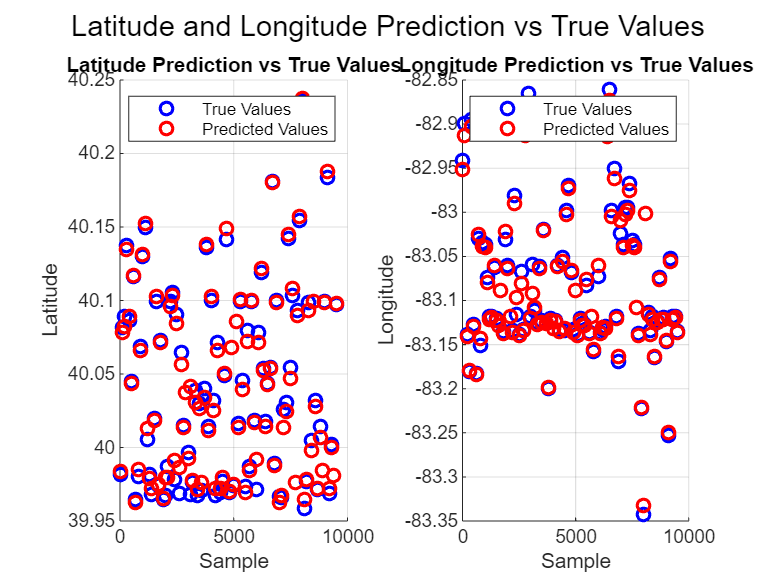


% Select every nth value for better legibility (e.g., every 100th point)
n = 100;  % Select every 100th point (you can adjust n as needed)

% Select the indices for the points to plot
indices = 1:n:length(y_latitude_test_seq);

% Plot the results for Latitude
figure;
subplot(1, 2, 1);
scatter(indices, y_latitude_test_seq(indices), 'b', 'LineWidth', 1.5); % True values for latitude
hold on;
scatter(indices, y_latitude_pred(indices), 'r', 'LineWidth', 1.5); % Predicted values for latitude
title('Latitude Prediction vs True Values');
xlabel('Sample');
ylabel('Latitude');
legend('True Values', 'Predicted Values');
grid on;

% Plot the results for Longitude
subplot(1, 2, 2);
scatter(indices, y_longitude_test_seq(indices), 'b', 'LineWidth', 1.5); % True values for longitude
hold on;
scatter(indices, y_longitude_pred(indices), 'r', 'LineWidth', 1.5); % Predicted values for longitude
title('Longitude Prediction vs True Values');
xlabel('Sample');
ylabel('Longitude');
legend('True Values', 'Predicted Values');
grid on;

% Improve layout
sgtitle('Latitude and Longitude Prediction vs True Values');


test_data = [ ...
    12.5, ...      % Speed (e.g., in m/s)
    0.3, ...       % Acceleration (m/s²)
    45.0, ...      % Heading (degrees)
    -0.1, ...      % Heading Change (degrees)
    40.748817, ... % Current Latitude (example near New York)
    -73.985428 ... % Current Longitude (example near New York)
];
test_data_normalized = (test_data - mu) ./ sigma;


test_seq = cell(1, 1);
test_seq{1} = repmat(test_data_normalized', [1, numTimeSteps]); % replicating test data across time steps

% Predict future latitude and longitude
pred_latitude_normalized = predict(LSTMModel_lat, test_seq);
pred_longitude_normalized = predict(LSTMModel_long, test_seq);

% Convert predictions back to original scale
pred_latitude = pred_latitude_normalized * y_latitude_std + y_latitude_mean;
pred_longitude = pred_longitude_normalized * y_longitude_std + y_longitude_mean;
    

disp(['Predicted Future Latitude: ', num2str(pred_latitude)]);

Predicted Future Latitude: 40.0315


disp(['Predicted Future Longitude: ', num2str(pred_longitude)]);

Predicted Future Longitude: -82.7037



test_data = table(64, 0.3, 92, 0.03, 34.052800, -118.243460, ...
    'VariableNames', {'Speed', 'Acceleration', 'Heading', 'HeadingChange', 'Latitude', 'Longitude'});

% Assuming mu and sigma are already defined from the training data
test_data_normalized = (test_data{:, :} - mu) ./ sigma;

% Assuming a sequence of 10 timesteps and all previous values available
sequence_length = 10;
X_test_seq = repmat(test_data_normalized, sequence_length, 1);
X_test_seq = X_test_seq';  % Transpose to match input format for LSTM

X_test_cell = {X_test_seq};

% Predict future latitude and longitude
predicted_latitude = predict(LSTMModel_lat, X_test_cell);
predicted_longitude = predict(LSTMModel_long, X_test_cell);

% Convert predictions back to original scale
predicted_latitude = predicted_latitude * y_latitude_std + y_latitude_mean;
predicted_longitude = predicted_longitude * y_longitude_std + y_longitude_mean;

disp(['Predicted Future Latitude: ', num2str(predicted_latitude)]);

Predicted Future Latitude: 40.0171


disp(['Predicted Future Longitude: ', num2str(predicted_longitude)]);

Predicted Future Longitude: -83.3523


SS_res_lat = sum((y_latitude_test_seq - y_latitude_pred).^2);  % Residual sum of squares for Latitude
SS_tot_lat = sum((y_latitude_test_seq - mean(y_latitude_test_seq)).^2);  % Total sum of squares for Latitude
R2_lat = 1 - (SS_res_lat / SS_tot_lat);  % R-squared for Latitude

% Calculate R-squared for Longitude
SS_res_long = sum((y_longitude_test_seq - y_longitude_pred).^2);  % Residual sum of squares for Longitude
SS_tot_long = sum((y_longitude_test_seq - mean(y_longitude_test_seq)).^2);  % Total sum of squares for Longitude
R2_long = 1 - (SS_res_long / SS_tot_long);  % R-squared for Longitude

% Display R-squared values
disp(['R-squared for Latitude Prediction: ', num2str(R2_lat)]);

R-squared for Latitude Prediction: 0.95345


disp(['R-squared for Longitude Prediction: ', num2str(R2_long)]);

R-squared for Longitude Prediction: 0.97199


test_sample = [36, -1.11, 348, 0, 40.109107, -83.178703];
test_sample_normalized = (test_sample - mu) ./ sigma;

% Define the sequence length
sequence_length = 10;

% Create a test sequence by repeating the normalized test data across the required time steps
X_test_seq = repmat(test_sample_normalized', [1, sequence_length]);

% Wrap the sequence in a cell array to match the expected input format
X_test_cell = {X_test_seq};

% Now you can use `predict` on this correctly formatted data
predicted_latitude = predict(LSTMModel_lat, X_test_cell);
predicted_longitude = predict(LSTMModel_long, X_test_cell);

% Convert predictions back to the original scale
predicted_latitude = predicted_latitude * y_latitude_std + y_latitude_mean;
predicted_longitude = predicted_longitude * y_longitude_std + y_longitude_mean;

% Display the predictions
disp(['Predicted Future Latitude: ', num2str(predicted_latitude)]);

Predicted Future Latitude: 40.1126


disp(['Predicted Future Longitude: ', num2str(predicted_longitude)]);

Predicted Future Longitude: -83.1816


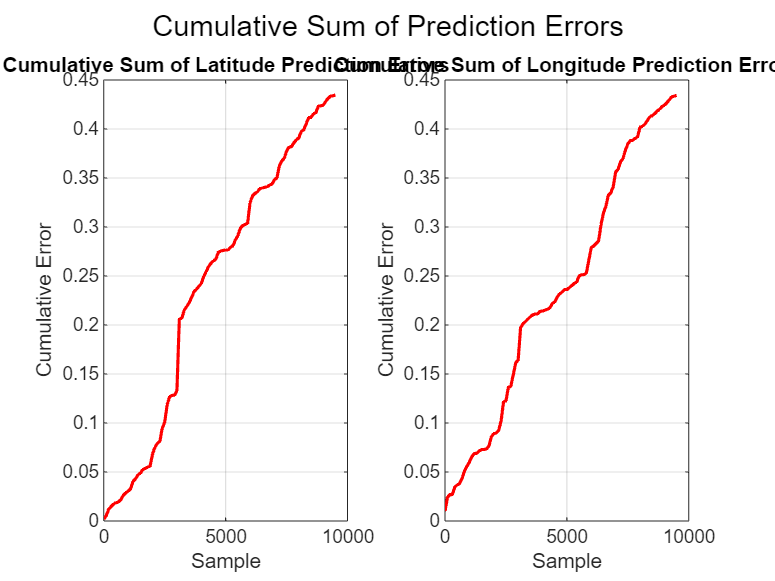

figure;
subplot(1, 2, 1);
plot(indices, cumsum(abs(y_latitude_test_seq(indices) - y_latitude_pred(indices))), 'r', 'LineWidth', 1.5);
title('Cumulative Sum of Latitude Prediction Errors');
xlabel('Sample');
ylabel('Cumulative Error');
grid on;

subplot(1, 2, 2);
plot(indices, cumsum(abs(y_longitude_test_seq(indices) - y_longitude_pred(indices))), 'r', 'LineWidth', 1.5);
title('Cumulative Sum of Longitude Prediction Errors');
xlabel('Sample');
ylabel('Cumulative Error');
grid on;
sgtitle('Cumulative Sum of Prediction Errors');